# **Introduction to Linear Algebra with MATLAB**

## MODULO 1 (BASI di MATLAB)

### Perché MATLAB?

MATLAB è una piattaforma di programmazione e calcolo numerico utilizzata da milioni di ingegneri e scienziati per l’analisi di dati, lo sviluppo di algoritmi e la creazione di modelli.

Per una rapida overview delle capacità del software, guarda questo breve video (1:37):

[https://www.youtube.com/watch?v=joilU9m-sNk&t=1s&ab_channel=MATLAB](https://www.youtube.com/watch?v=joilU9m-sNk&t=1s&ab_channel=MATLAB)

Digitando il comando `demo` seguito da invio nella Command Window, si aprirà una pagina web con moltissimi esempi di utilizzo, catalogati per aree tematiche.

%demo

### 1.1: Default layout e Command Window

*Questa sezione non contiene codice: verrà tutto svolto nella Command Window*

Il layout di default contiene tre pannelli: **Current Folder** (sx), **Command Window** (cx), **Workspace** (dx).

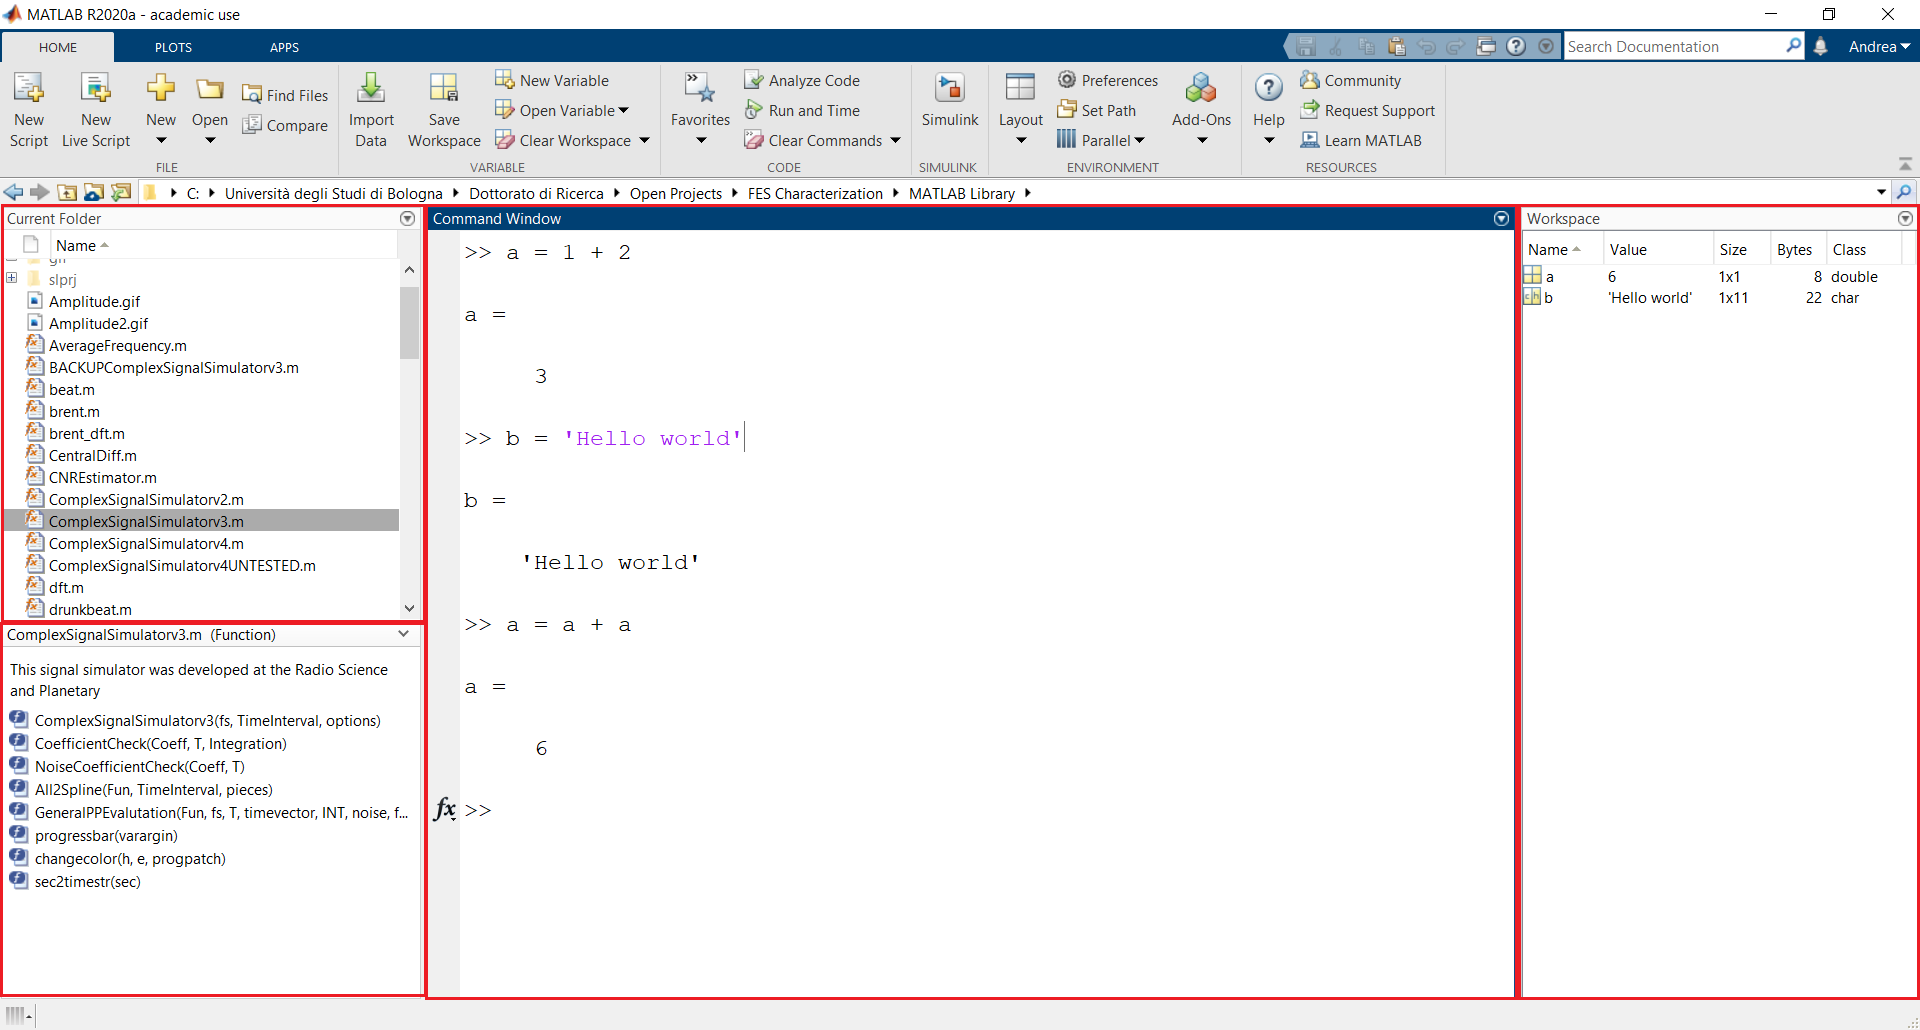

Quando inizi a lavorare su un nuovo problema è buona pratica **ripulire il Workspace**: utilizza il comando *clear all* per eliminare tutte le variabili salvate, e il comando *clc* per pulire la Command Window

### 1.2: Live Editor

Inserire i comandi nella command window è un modo veloce per fare delle prove e vedere i risultati, ma risolvere problemi spesso richiede molte righe di codice e comandi.

Potete salvare le righe di codice e gli output insieme creando un **live script**: clicca in alto su *New Live Script* nella Home Tab per crearne uno.

Il live script è uno strumento molto potente: puoi inserire i comandi nell’**area grigia**, cambiare in **testo** (Text) per aggiungere descrizioni, e cliccare su **run** per eseguire tutto il live script. L’output viene salvato a destra, ma puoi cambiare il layout. Puoi anche dividere il tuo codice in sezioni (*Section Break*), per eseguire solo una porzione di codice per volta con “Run section”. Cliccando sul codice verrà evidenziato l'output corrispondente e viceversa.

Cliccando su *Save* puoi salvare il codice, ouput e testo, sia in formato nativo (*.mlx*) che in pdf. Da ora in avanti useremo il Live Script, e ti incoraggiamo a fare lo stesso quando userai MATLAB in futuro!

Prima di cominciare, scriviamo i tre comandi che resettano l'ambiente. 

- `clc`: pulisce la Command Window

- `clear all: `cancella tutte le variabili salvate

- `close all:` chiude tutte le figure aperte

### **1.3: Eseguire Semplici Comandi e Definire Variabili**

Operatori matematici di base:

`    +   Somma`

`    -   Differenza`

`    *   Prodotto`

`    /   Rapporto`

`    ^   Elevamento a potenza`

Il simbolo (=) in MATLAB è un operatore di *assegnamento*, che assegna l'espressione a destra alla variabile a sinistra. Nota che nella finestra **Workspace** vengono salvate tutte le variabili create, e scrivendo solo il nome della variabile ne verrà mostrato il valore attuale. 

Puoi chiamare le tue variabili come vuoi, a patto che inizino con una lettera e contengano solo lettere, numeri e underscores (_). Le variabili sono anche Case Sensitive: ad esempio, *Apple* è diverso da *apple*.

E' possibile eseguire comandi direttamente nella COMMAND WINDOW dopo il simbolo >> , premere invio per eseguire il codice:

18*4

ans = 72

MATLAB salva il risultato delle operazioni eseguite in Command Window nel Workspace come "ans". 

### 1.4: Costanti e Funzioni Built-in

Costanti built-in:

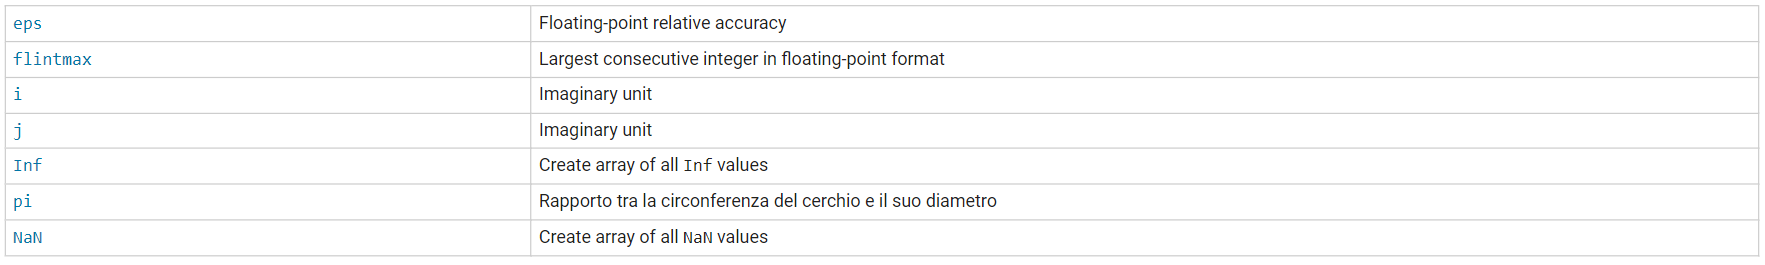

Funzioni built-in:

help elfun

  Elementary math functions.
 
  Trigonometric.
    sin         - Sine.
    sind        - Sine of argument in degrees.
    sinh        - Hyperbolic sine.
    asin        - Inverse sine.
    asind       - Inverse sine, result in degrees.
    asinh       - Inverse hyperbolic sine.
    cos         - Cosine.
    cosd        - Cosine of argument in degrees.
    cosh        - Hyperbolic cosine.
    acos        - Inverse cosine.
    acosd       - Inverse cosine, result in degrees.
    <a href="m

### 1.5: Creazione di array

*MATLAB* è un'abbreviazione di "matrix laboratory", "laboratorio di matrici". Mentre altri linguaggi di programmazione lavorano principalmente su un numero per volta, MATLAB consente di operare soprattutto su intere matrici e array.

Tutte le variabili di MATLAB sono *array* multidimensionali, indipendentemente dal tipo di dati. Una *matrice* è un array bidimensionale frequentemente utilizzato nell'algebra lineare.

Un numero singolo, chiamato *scalare*, è salvato in MATLAB come un array 1x1, contenente una riga e una colonna.

- Puoi creare array con elementi multipli usando le parentesi quadre: separando i numeri con spazi viene creato un vettore **riga **(1xn), separando i numeri col punto e virgola vengono creati vettori **colonna **(nx1):

% Vettore riga
x = [3 5]

x =      3     5



% Vettore colona
y = [3; 5]

y =      3
     5



% Matrice
M = [3, 5, 6;
     6, 1, 4]

M =      3     5     6
     6     1     4


- Puoi usare la tecnica sequenziale:

% Passo fissato
y = 0:2:10

y =      0     2     4     6     8    10



% Passo fisso inverso
y = 10:-2:0

y =     10     8     6     4     2     0



% Trasposto
x = (1:5)'

x =      1
     2
     3
     4
     5



% Linspace
z = linspace(1, 5, 10)

z =     1.0000    1.4444    1.8889    2.3333    2.7778    3.2222    3.6667    4.1111    4.5556    5.0000


- Funzioni per generare velocemente matrici fondamentali:

% Ones
x = ones(2,3)

x =      1     1     1
     1     1     1



% Zeros
v = zeros(4)

v =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0



% Rand
z = rand(2)

z =     0.8147    0.1270
    0.9058    0.9134



% Identity
M = eye(5)

M =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


### 1.6: Indexing

Dato che tutto le variabili in MATLAB sono array, è fondamentale imparare come usarli, come riferirsi a elementi specifici per estrarre o modificare valori: in altre parole, come effettuare l'**indexing**.

La posizione di un valore in un array è chiamata *indice*. Puoi usare l'indice per modificare o estrarre il valore, per esempio, se vuoi il terzo elemento del vettore:

x = (1:10)'

x =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10



M = [(1:3)', (4:6)', (7:9)']

M =      1     4     7
     2     5     8
     3     6     9


**N.B.:** in MATLAB, si conta **a partire da 1 **e la numerazione matriciale è per **colonna**.

x = [10, 18, 20, 1];
y = [17, 3, 1, 2]';
M = [10, 3, 7;
     2, 12, 9];

% Prendi il numero 18 da x
x_18 = x(2)

x_18 = 18


% Prendi il primo e l'ultimo elemento da y
y_17_1 = y([1, end])

y_17_1 =     17
     2



% Prendi la prima riga da M
M_row = M(1,:)

M_row =     10     3     7


#### 1.6.1: Funzioni utili per maneggiare Array

In MATLAB puoi usare comodissime funzioni built-in per maneggiare vettori ed elementi dei vettori attraverso un linguaggio di ALTO LIVELLO:

- Funzione `find( ) `permette di trovare l'indice dell'elemento

- Fuzione `max( )` permette di trovare il massimo elemento

- Funzione `min( )` permette di trovare il minimo elemento

- Funzione `sort( ) `permette di riordinare gli elementi

x = [20, 2, 49, 30]

x =     20     2    49    30



% find()
val = find(x == 49) % Numerazione per colonna

val = 3


% max(), min()
M_max = max(x)

M_max = 49

M_min = min(x)

M_min = 2


% sort()
x_sort = sort(x)

x_sort =      2    20    30    49


### 1.7 Operazioni con Matrici

MATLAB è pensato per lavorare naturalmente su array: la maggiore parte delle operazioni funziona coi vettori

x = [5 2 3]

x =      5     2     3


y = [4 5 6]

y =      4     5     6



% Aggiungere uno scalare a ogni elemento
y = x + 2

y =      7     4     5



% Sommare due elementi della stessa lunghezza
z = x + y

z =     12     6     8



% Moltiplicare o dividere ciascun elemento per uno scalare
z = 2*x

z =     10     4     6


y = x/3

y =     1.6667    0.6667    1.0000



% Eseguire la radice quadrata di ogni elemento
xSqrt = sqrt(x)

xSqrt =     2.2361    1.4142    1.7321


L'operatore * consente di effettuare la **moltiplicazione tra matrici**: se vuoi effettuare un prodotto tra vettori di uguale dimensione (tipo prodotto scalare) comparirà un errore.

% z = [3 4] * [10 20]

Per effettuare un prodotto elemeneto per elemento devi utilizzare l'operatore .*

z = [3 4] .* [10 20]

z =     30    80


## MODULO 2 (Risoluzioni di sistemi lineari)

### 2.1: Equazioni lineari

Una equazione lineare è una equazione con solamente due tipi di termini: *costanti* e *variabili moltiplicate da costanti*.

Scriviamo ad esempio l'equazione con:

- Costanti: 5, 0;

- Variabili moltiplicate da costanti: 2x, -y;


$$2x-y+5=0$$


Equazioni che non rispettano queste caratteristiche sono dette **NON lineari**.

### 2.2: Sistemi lineari

Un sistema lineare è un sistema in cui sono presenti solo equazioni lineari. 

Per risolvere un sistema di questo tipo con MATLAB dobbiamo trasformarlo in un problema di tipo matriciale:


$$\begin{cases}
2x +( -1)y + 3z = 1 \\
4x + 2y - 2z = 2 \\
1x + y + z = 3
\end{cases}$$
 
$$\Longrightarrow$$
 
$$\left\lbrack \begin{array}{ccc}
2 & -1 & 3\\
4 & 2 & -2\\
1 & 1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
2\\
3
\end{array}\right\rbrack$$


Notiamo che le due matrici che vengono moltiplicate devono avere dimensioni compatibili.

Considerando la moltiplicazione tra una matrice 3×3 e un vettore colonna 3×1: gli elementi della prima riga della matrice vengono moltiplicati per i corrispondenti elementi del vettore colonna; i prodotti vengono poi sommati per ottenere il primo elemento del vettore colonna risultante; analogamente, gli elementi corrispondenti della seconda riga della matrice e del vettore colonna vengono moltiplicati e sommati, dando il secondo elemento del vettore colonna risultante.

Considerado il caso precedente otterremo:

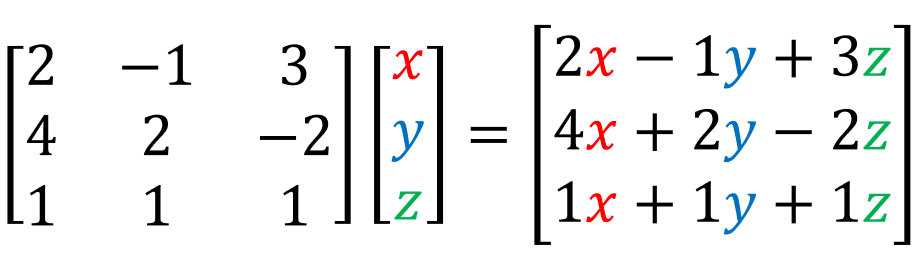

A = [2, -1, 3; 
     4, 2, -2; 
     1, 1, 1];

b = [1; 2; 3];

Vogliarmo trovare il vettore delle incognite **x**.

#### Metodo 1: Usare l'inversa della matrice

È possibile risolvere il sistema usando l'inversa della matrice **A **con il comando `inv()`.

x_inv = inv(A) * b

x_inv =          0
    2.0000
    1.0000


Tuttavia, questo metodo è meno efficiente e può portare a errori numerici, quindi non è raccomandato per sistemi di grandi dimensioni.

#### Metodo 2: Usare la funzione `linsolve()`

 MATLAB offre una funzione chiamata `linsolve()` per risolvere sistemi di equazioni lineari.

x_linsolve = linsolve(A, b)

x_linsolve =      0
     2
     1


#### Metodo 3: Usare l'operatore backslash (\)

Un altro modo rapido per risolvere sistemi lineari è usare l'operatore backslash (\).

Questo metodo permette di utilizzare un metodo numerico ottimizzato per la risoluzione del sistema numerico, riduecendo gli errori numerici al minimo, è dunque il metodo da preferire se si vuole in generale risolvere un sistema lineare generico.

x_backslash = A \ b

x_backslash =      0
     2
     1


#### Verifica della Soluzione

Possiamo verificare che le soluzioni ottenute siano corrette controllando se **Ax = b**.

Se le soluzioni sono corrette, i valori di **b** calcolati dovrebbero essere uguali a quelli originali.

b_verifica_linsolve = A * x_linsolve

b_verifica_linsolve =      1
     2
     3


b_verifica_backslash = A * x_backslash

b_verifica_backslash =      1
     2
     3


b_verifica_inv = A * x_inv

b_verifica_inv =     1.0000
    2.0000
    3.0000



% format long
% b_verifica_inv


### 2.3: Sistemi con più soluzioni o senza soluzioni

Non tutti i sistemi di equazioni lineari hanno una soluzione unica. Un sistema può avere:

- Una soluzione unica

- Nessuna soluzione (il sistema è sovradeterminato): nel caso si abbiano più equazioni che incognite

- Infinite soluzioni (il sistema è indeterminato): nel caso in cui si abbiano meno equazioni che incognite

#### Esempio di sistema senza soluzioni (sistema sovra determinato):


$$\begin{cases}
1x + 1y = 1 \\
1x + 2y = 1 \\
12x + 7y = 4
\end{cases}$$

$$\Longrightarrow$$

$$\begin{cases}
x = 1 \\
y = 0 \\
x = \frac{1}{3}
\end{cases}$$


A_ns = [1, 1;
        1, 2;
        12, 7];

b_ns = [1; 1; 4];

Se il sistema **non** ha soluzioni, l'operatore \ ritornerà il miglior vettore di soluzioni che minimizza dell'errore.

x_ns = A_ns \ b_ns

x_ns =     0.0095
    0.5587


#### Esempio di sistema con infinite soluzioni (sistema indeterminato):


$$\begin{cases}
1x + 2y + 3z = 3 \\
3x + 2y + 4z= 6
\end{cases}$$


A_inf = [1, 2, 3;
         3, 2, 4];

b_inf = [3; 6];

Se il sistema ha **infinite soluzioni**, l'operatore \ ritorna la soluzione con il maggior numero di soluzioni

x_inf = A_inf \ b_inf

x_inf =     1.2000
         0
    0.6000


#### Casi speciali: Matrici singolari

Esistono casi in cui la matrice **A** è quadrata ma il sistema non ha soluzione o ne ha infinite, in questo caso la matrice è detta singolare. 

Questo è dovuto al fatto che l'inversa di A è una matrice con valori vicini a zero o infiniti.

A_ns = [1, 1; 
        1, 1];
b_ns = [1; 2];

% check inversa di A
inv(A_ns) 

ans =    Inf   Inf
   Inf   Inf


Usando l'operatore backslash, MATLAB tornerà una soluzione particolare, avvisando che **A** è singolare

x_ns = A_ns \ b_ns

x_ns =   -Inf
   Inf


### 2.4 Esercizio: 

Risolvi il seguente sistema di equazioni:


$$\begin{cases}
3x + 4y + 2z = 1 \\
2x - y + 4z = 2 \\
x + y + z = 3
\end{cases}$$


- Rappresenta il sistema in forma matriciale.

- Risolvilo usando i diversi metodi descritti sopra.

- Verifica la soluzione.

% SOLUZIONE:
A_ex = [3, 4, 2; 
        2, -1, 4;
        1, 1, 1];

b_ex = [1; 2; 3];

x_bcslash = A_ex\b_ex;
x_linsolve = linsolve(A_ex, b_ex);
x_inv = inv(A_ex)*b_ex;

% Verifica
b_verifica_backslash = A_ex*x_bcslash

b_verifica_backslash =     1.0000
    2.0000
    3.0000


b_verifica_linsolve = A_ex*x_linsolve

b_verifica_linsolve =     1.0000
    2.0000
    3.0000


b_verifica_inv = A_ex*x_inv

b_verifica_inv =     1.0000
    2.0000
    3.0000


## MODULO 3 (Autovalori ed Autovettori)

In questa lezione, esploreremo come calcolare gli autovalori e gli autovettori di una matrice utilizzando MATLAB.

Una matrice può essere rappresentata attraverso i suoi **autovalori **ed **autovettori**. Questo tipo di rappresentazione è chiamata **decomposizione agli autovalori **ed è rappresentata dalla seguente equazione:


$$\underline{\underline{\mathit{\mathbf{A}}} } \;\underline{v} =\lambda \underline{v}$$


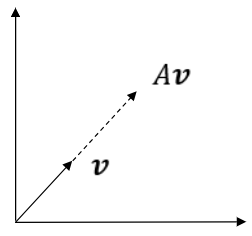

dove:

- $\underline{\underline{\mathit{\mathbf{A}}} }$ è una matrice quadrata

- $\underline{v}$ è un vettore non nullo

- $\lambda$ è uno scalare

Il concetto dietro ad autovalore ed autovettore sta nel fatto che: quando moltiplichiamo una matrice per il suo autovettore abbiamo lo stesso effetto che potremmo avere moltiplicando il vettore (autovettore) per una costante che è l'autovalore.

Effettuando $\underline{\underline{\mathit{\mathbf{A}}} } \;\underline{v}$ andiamo quindi ad incrementare il modulo del vettore senza cambiare la sua direzione e verso.

Questo ci permette di semplificare notevolmente la risoluzione di problemi ingegneristici.

### 3.1: Calcolo degli autovalori ed autovettori con MATLAB

 In MATLAB, possiamo calcolare gli autovalori e gli autovettori di una matrice usando la funzione `eig()`.

A = [4, -2; 
     1, 1];

% Funzione eig()
[V, D] = eig(A);

Le colonne della matrice **V** sono gli autovettori corrispondenti, mentre la matrice **D** contiene gli autovalori sulla diagonale principale.

Estraiamo dunque le colonne di **V ** come autovettori e la diagonale di **D ** come autovalori:

% Estrai le colonne di V
v1 = V(:,1)

v1 =     0.8944
    0.4472


v2 = V(:,2)

v2 =     0.7071
    0.7071



% Estrai gli elementi di D
lambda1 = D(1,1)

lambda1 = 3

lambda2 = D(2,2)

lambda2 = 2

#### Verifica degli Autovalori e Autovettori

Verifichiamo che $\underline{\underline{\mathit{\mathbf{A}}} } \;\underline{v} =\lambda \underline{v}$ sia vero per ogni autovalore e autovettore.

Primo autovalore e autovettore

Av1 = A * v1

Av1 =     2.6833
    1.3416


lambda_v1 = lambda1 * v1

lambda_v1 =     2.6833
    1.3416


Secondo autovalore e autovettore

Av2 = A * v2

Av2 =     1.4142
    1.4142


lambda_v2 = lambda2 * v2

lambda_v2 =     1.4142
    1.4142


Se i risultati sono uguali, allora l'autovalore e l'autovettore sono corretti.

### 3.2: Autovalori Complessi

Non tutte le matrici hanno autovalori reali. Le matrici possono anche avere autovalori complessi.

% Esempio:
A_complex = [0, -1; 
             1, 0];

% Calcoliamo gli autovalori e autovettori
[V_complex, D_complex] = eig(A_complex)

V_complex =    0.7071 + 0.0000i   0.7071 + 0.0000i
   0.0000 - 0.7071i   0.0000 + 0.7071i


D_complex =    0.0000 + 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 1.0000i


### 3.3: Applicazioni degli Autovalori

Gli autovalori e autovettori hanno molte applicazioni pratiche, d esempio possono essere utilizzati per

- La decomposizione spettrale

- Analizzare la stabilità dei sistemi dinamici 

- Riduzione dimensionale come nel Principal Component Analysis (PCA).

### **3.4: Esercizio**

Considera la matrice seguente

A_ex = [2, 1; 
        1, 2];

- Trova gli *autovalori* e gli *autovettori* di A_ex usando `eig().`

- Verifica che $\underline{\underline{\mathit{\mathbf{A}}} } \;\underline{v} =\lambda \underline{v}$ per ciascun autovalore e autovettore attraverso un ciclo `for`.

% SOLUZIONE:
[V, D] = eig(A_ex);

% Verifica:
for i = 1:length(A)

    lambda_i = D(i,i);
    v_i = V(:,i);
    Av_ex1 = A_ex * v_i;
    lambda_v_ex1 = lambda_i * v_i;

    if Av_ex1 == lambda_v_ex1
        fprintf('Verificato prer autovalore %i \n \n', i)
    else
        warning('NON verificato!!! \n \n')
    end
end

Verificato prer autovalore 1 
 
Verificato prer autovalore 2 
 


## MODULO 4 (Plotting Data)

Su MATLAB è possibile realizzare moltissime tipologie di grafici:

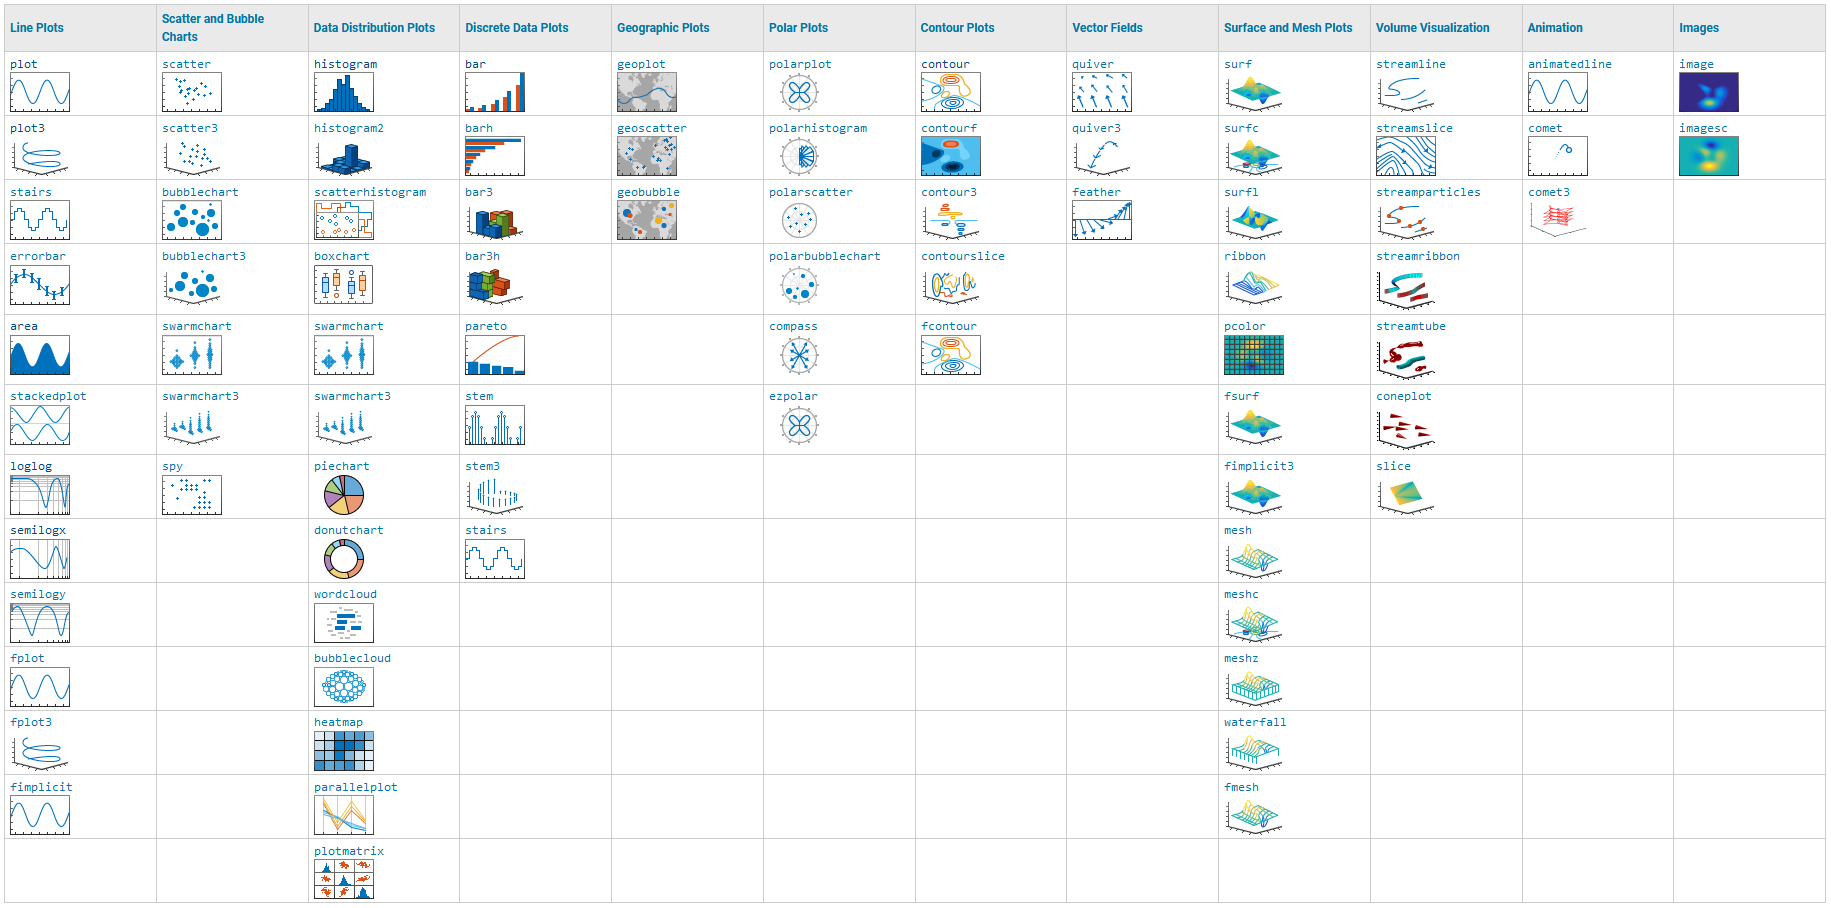

In questo modulo utilizzeremo il comando `plot`, il funzionamento di questo comando è vario e dipende dai parametri che gli passeremo come input. Per capirne il funzionamento, ti consigliamo di scrivere nella comandan window `help plot`.

Tutte le funzioni built-in di MATLAB sono ben documentate. E' possibile accedere alla documentazione direttamente da MATLAB.

Il comando `help nome_funzione` restituisce un breve riassunto della documentazione in formato testuale.

% help plot

l comando `doc nome_funzione` apre una pagina web con l'intera documentazione:

% doc plot

### 4.1: Plottare vettori

Due vettori della stessa lunghezza possono essere rappresentati uno contro l'altro usando la funzione *plot*.

clc
clear all

mass_m = [75 78 96 74 81 67 59 65 72 82];
height_m = [172 173 169 171 168 180 171 170 170 179];

mass_f = [58 55 68 65 45 59 64 60 61 57];
height_f = [161 160 170 165 158 163 180 175 178 164];

Puoi utilizzare input aggiuntivi della funzione plot per specificare colore, tipo di linea, tipo di marker usando simboli differenti tra virgolette. MATLAB suggerisce da solo altri tipi di input che puoi utilizzare, come *LineWidth, MarkerSize *o *MarkerEdgeColor.*

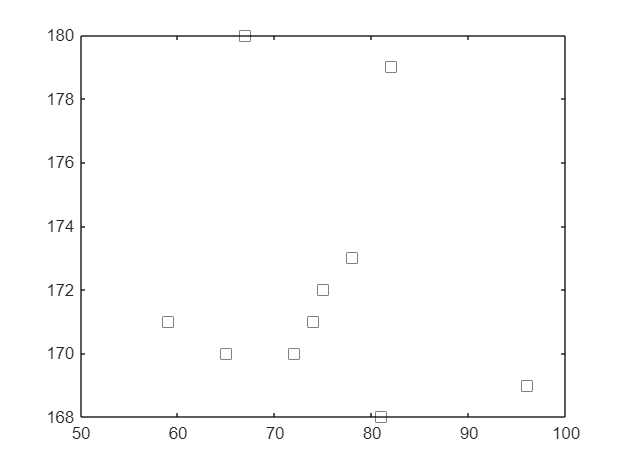

% Plot mass_m VS height_m con quadrati neri:
plot(mass_m, height_m, 'ks', 'Markersize',8) % il grafico viene automaticamente unito con una spezzata

Nota che tutti i plot creano dei nuovi grafici. Se vuoi disegnari i grafici uno sopra l'altro puoi utilizzare il comando *hold on*. Ricordati di utilizzare il comando *hold off* quando hai finito, in modo tale che i grafici successivi non continuino a sovrapporsi.

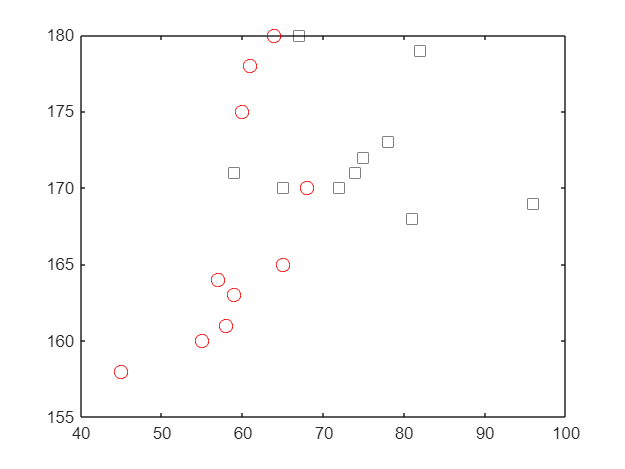

% Plot entrmabe mass_m, mass_f VS height_m height_f
plot(mass_m, height_m, "ks", 'MarkerSize', 8)
hold on
plot(mass_f, height_f, "ro", 'MarkerSize', 8)
hold off

### 4.2: Plottare funzioni

Per plottare funzioni ci sono diverse opzioni, la prima è usare il comando *plot* creando un vettore di punti denso in corrispondenza dell'intervallo sull'asse x in cui si vuole disegnare il grafico della funzione. Più punti ci sono nel vettore, meglio sarà rappresentato il grafico.

`Crea un vettore x di 100 punti da 0 a 2*pi`

`Con il comando plot(ascisse, ordinate) rappresenta la funzione cos(x) `

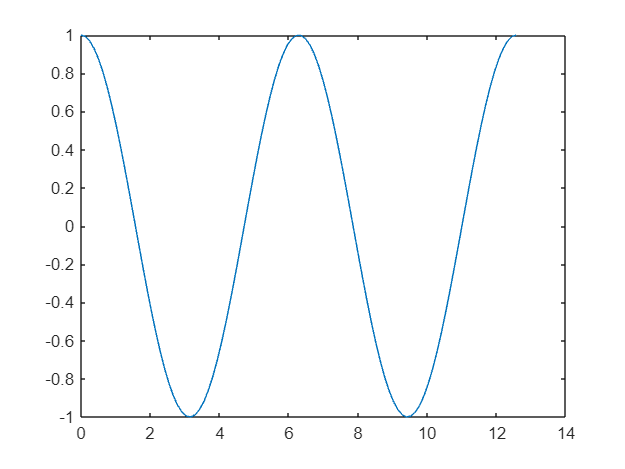

x = linspace(0,4*pi,100);

% Plot coseno:
y = cos(x);
plot(x,y)

Un metodo più comodo per plottare funzioni semplici o ben definite è definire le *anonymous function*, usando le **function handle** in combinazione con la funzione *fplot*. 

`anonymous function = @(lista variabili) espressione`

utilizza il comando` fplot(funzione, [a, b]) `disegna $x^3 +3\;x^2$ (ricorda il .^) da -3 a 3

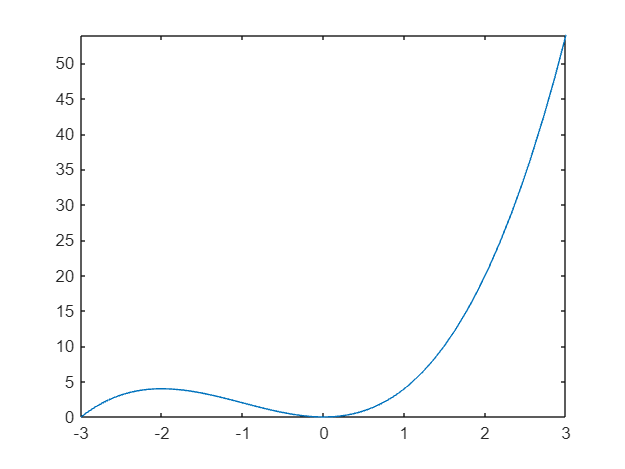

f = @(x) x.^3 + 3*x.^2;

% Usa fplot tra [-3,3]
fplot(f, [-3,3])

### 4.3: Personalizzare i Grafici

E' possibile personalizzare il grafico in molti modi, vediamo come:

**Personalizzazione Rapida - Aspetto della Linea e Aggiunta di Marker**

Il modo più veloce consiste nell'aggiungere agli input (x,y) un terzo argomento che contenga una combinazione dei valori riportati nelle seguenti tabelle.

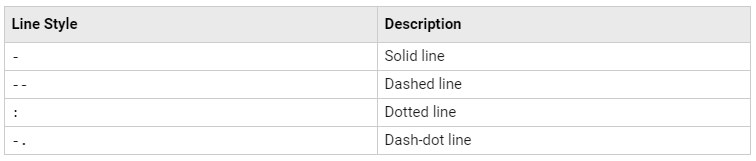

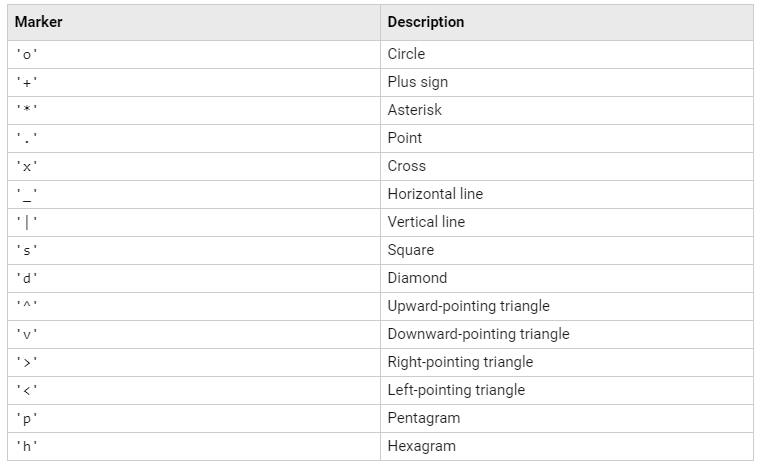

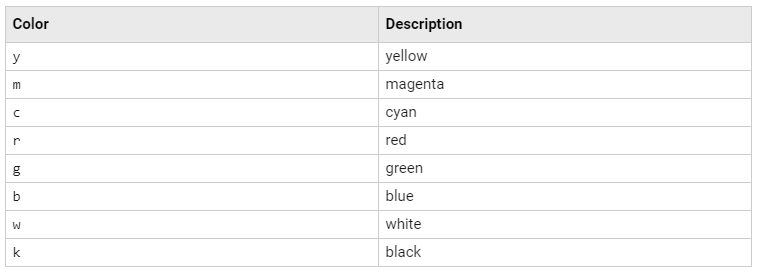

Vi lasciamo un esempio di plot con altre impostazioni che potrete utilizzare in futuro come template:

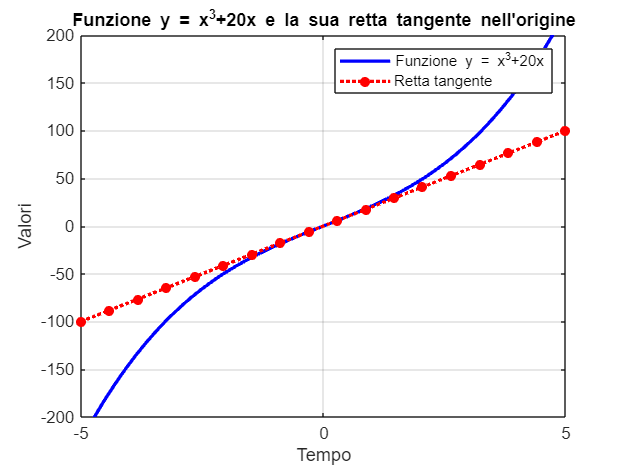

f = @(x) x.^3 +20.*x;

retta_tan = @(x) 20.*x;

figure()
fplot(f, 'b-', 'LineWidth', 2)
hold on 
fplot(retta_tan, ':*r', 'LineWidth', 2)
xlim([-5, 5])
ylim([-200, 200])
grid on
title("Funzione y = x^{3}+20x e la sua retta tangente nell'origine")
legend("Funzione y = x^{3}+20x", "Retta tangente")
xlabel('Tempo')
ylabel('Valori')
hold off

## MODULO 5 (Applicazione: Eigenanalysis di oscillatore armonico) 

Questo esempio illustra l'uso dell'eigenanalysis per studiare la stabilità di un sistema dinamico semplice. Consideriamo un sistema di controllo lineare con due stati: posizione e velocità. La dinamica del sistema è descritta da una matrice di stato A.

L'obiettivo è determinare se il sistema è stabile e osservare il comportamento della sua risposta nel tempo.

### **5.1: Descrizione del Sistema**

Consideriamo un sistema costituito da:

- Una massa *m* collegata a una molla con costante elastica *k*.

- Uno smorzatore (o ammortizzatore) con coefficiente di smorzamento *c*.

Il sistema è libero di oscillare dalla posizione di partenza in cui si trova senza applicazione di forzanti esterne. Il moto della massa è descritto dalla sua posizione *x(t)* rispetto a un punto di equilibrio.

### **5.2: Equazione Differenziale del Sistema**

L'equazione differenziale che descrive il moto della massa è data dalla seconda legge di Newton, che per questo sistema diventa:


$$m\ddot{x}(t)+c\dot{x}(t)+kx(t)=0$$


### **5.3: Modello nello Spazio degli Stati**

L'utilizzo dei concetti di autovalore ed autovettore ci permette, passando all nella forma agli stati del problema (non entreremo del dettaglio su come arrivare a questa formulazione) ad investigare la stabilità del nostro sistem.

L'equazione agli stati ci permette di passare dalla equazione equazione diefferenziale precedente al seguente sistema matriciale:


$$\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{k}{m} & -\frac{c}{m}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack \;\Longrightarrow \;\;\dot{x} =\mathit{\mathbf{A}}\;x$$


dove:


$$x=\left\lbrack \begin{array}{c}
x\left(t\right)\;\;\;\;\;\;\;\left(\textrm{posizione}\right)\\
\dot{x} \left(t\right)\;\;\;\;\;\;\;\;\;\;\left(\textrm{velocità}\right)
\end{array}\right\rbrack$$


clc;
clear all;

% Definizione del Sistema Dinamico
A = [0 1;
     -2 -3]; % Stabile

% A = [0 -1.4;
%      -2 -3];  % Instabile

% A = [0 1;
%      -2 -3]; % Marginalmente stabile

% Calcoliamo gli autovalori e gli autovettori della matrice di stato A
[eigenvectors, eigenvalues] = eig(A);

% Visualizziamo gli autovalori e autovettori
disp('Autovalori (Eigenvalues):');

Autovalori (Eigenvalues):


disp(diag(eigenvalues));  % Gli autovalori sono i valori diagonali della matrice eigenvalues

    -1
    -2




disp('Autovettori (Eigenvectors):');

Autovettori (Eigenvectors):


disp(eigenvectors);

    0.7071   -0.4472
   -0.7071    0.8944



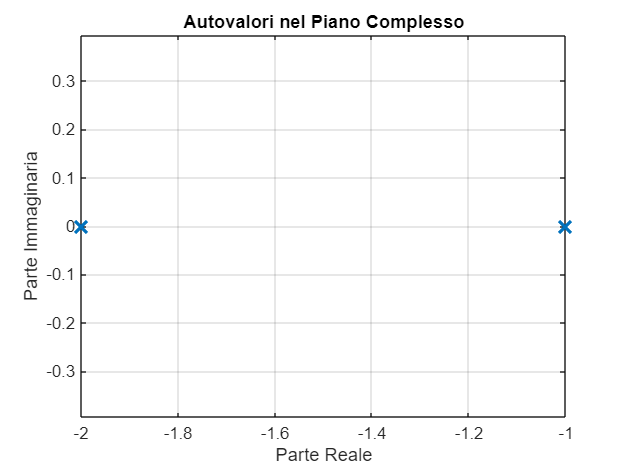




% Grafico degli autovalori nel piano complesso
figure;
plot(real(diag(eigenvalues)), imag(diag(eigenvalues)), 'x', 'MarkerSize', 10, 'LineWidth', 2);
grid on;
xlabel('Parte Reale');
ylabel('Parte Immaginaria');
title('Autovalori nel Piano Complesso');
axis equal;

Gli autovalori determinano la stabilità del sistema:

- Se tutti gli autovalori hanno **parte reale negativa**, il sistema è **stabile**.

- Se almeno un autovalore ha **parte reale positiva**, il sistema è **instabile**.

- Se tutti gli autovalori hanno **parte reale nulla**, il sistema è **marginalmente stabile**.


real_parts = real(diag(eigenvalues));
if all(real_parts < 0)
    disp('Il sistema è stabile.');
    stability_msg = 'Sistema Stabile';
elseif any(real_parts > 0)
    disp('Il sistema è instabile.');
    stability_msg = 'Sistema Instabile';
else
    disp('Il sistema è marginalmente stabile.');
    stability_msg = 'Sistema Marginalmente Stabile';
end

Il sistema è stabile.


Simulazione della Risposta del Sistema, sapendo che l'equazione del moto sarà:


$$x\left(t\right)=e^{\left(\mathit{\mathbf{A}}\cdot t\right)} x_0$$


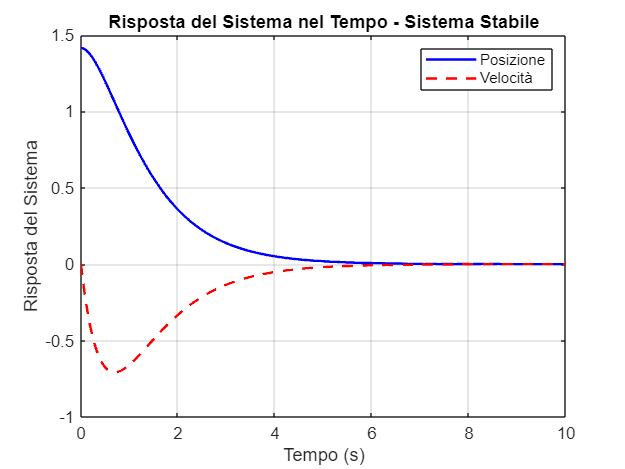


% Condizioni iniziali: posizione e velocità iniziali
x0 = [sqrt(2); 0];

% Tempo di simulazione
t = 0:0.01:10;

% Calcoliamo l'esponenziale della matrice A*t per ogni istante temporale
x = zeros(2, length(t));  % Inizializzazione del risultato

for i = 1:length(t)
    x(:, i) = expm(A * t(i)) * x0;
end

%% Plot della Risposta del Sistema
figure;
plot(t, x(1, :), 'b-', 'LineWidth', 1.5);
hold on;
plot(t, x(2, :), 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Tempo (s)');
ylabel('Risposta del Sistema');
legend('Posizione', 'Velocità');
title(['Risposta del Sistema nel Tempo - ' stability_msg]);

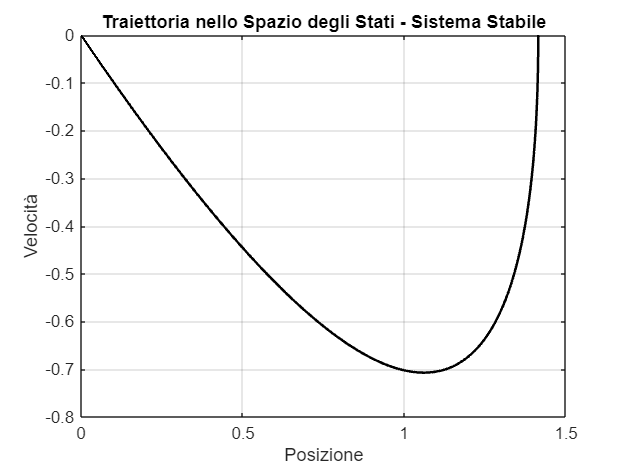


% Grafico della traiettoria nello spazio degli stati (posizione vs velocità)
figure;
plot(x(1, :), x(2, :), 'k-', 'LineWidth', 1.5);
grid on;
xlabel('Posizione');
ylabel('Velocità');
title(['Traiettoria nello Spazio degli Stati - ' stability_msg]);